specs = make_imaging_specs();
full_dir = ('/Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/1000LNPSolutions/spherical_solutions');
build_sphere_population(full_dir, 100, 99, 46, specs, 1001, 'full');

saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/1000LNPSolutions/spherical_solutions/full_001_mesh.mat (d = 75.2 nm)
saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/1000LNPSolutions/spherical_solutions/full_002_mesh.mat (d = 63.7 nm)
saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/1000LNPSolutions/spherical_solutions/full_003_mesh.mat (d = 69.4 nm)
saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/1000LNPSolutions/spherical_solutions/full_004_mesh.mat (d = 89.8 nm)
saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/1000LNPSolutions/spherical_solutions/full_005_mesh.mat (d = 36.4 nm)
saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/1000LNPSolutions/spherical_solutions/full_006_mesh.mat (d = 36.4 nm)
saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/1000LNPSolutions/spherical_solutions/full_007_m

Solving 100 full spheres (parallel)...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.



%% ========================================================================
% 3) BLEBBED LNPs  (fused single-envelope geometry, lean mesh storage)
% ========================================================================
n_lipid   = 1.495;   % Leslie & Cullis
n_aqueous = 1.45;    % placeholder
mat_lipid   = Material(n_lipid^2, 1);
mat_aqueous = Material(n_aqueous^2, 1);
mat_set_bleb = [mat_glass, mat_medium, mat_lipid, mat_aqueous];
idx_glass = 1; idx_water = 2; idx_lipid = 3; idx_aqueous = 4; %#ok<NASGU>

N_bleb = 1000;
d_mean_core = 70; d_sd_core = 20;
d_mean_bleb = 50; d_sd_bleb = 10;
neck_overlap_frac_min = 0.3;   % fraction of the smaller sphere's radius, uniform draw
neck_overlap_frac_max = 0.9;
step     = 1;   % nm, raster voxel size
radbound = 6;   % nm, target surface-triangle edge length
randomize_orientation = true;

base_seed = 12345;             % change for a different population, but keep it recorded
rng(base_seed);

mesh_dir = fullfile(out_dir, 'meshes');
if ~exist(mesh_dir, 'dir'), mkdir(mesh_dir); end

max_attempts = 50;   % guard against an endless retry loop

for k = 589:N_bleb
    fn = fullfile(mesh_dir, sprintf('bleb_%03d_mesh.mat', k));
    ok = false;

    for attempt = 1:max_attempts
        % Draw parameters (rejecting unresolvably thin blebs)
        while true
            d_core = d_mean_core + d_sd_core * randn;
            d_bleb = d_mean_bleb + d_sd_bleb * randn;
            neck_overlap_frac = neck_overlap_frac_min + ...
                (neck_overlap_frac_max - neck_overlap_frac_min) * rand;
            neck_overlap = neck_overlap_frac * min(d_core, d_bleb) / 2;
            if d_core > 0 && d_bleb > 0 && d_bleb > neck_overlap + 4 * step
                break;
            end
        end

        if randomize_orientation
            theta_tilt_deg = acosd(2*rand - 1);   % uniform over the sphere
            phi_azimuth_deg = 360 * rand;
        else
            theta_tilt_deg = 90;
            phi_azimuth_deg = 0;
        end

        % Already saved: skip, so reruns resume (draws above still ran)
        if exist(fn, 'file'), ok = true; break; end

        try
            mesh = build_fused_bleb_mesh(d_core, d_bleb, neck_overlap, step, radbound, gap, ...
                theta_tilt_deg, phi_azimuth_deg);
            ok = true;
        catch ME
            fprintf('k=%d attempt %d failed: %s\n', k, attempt, ME.message);
        end
        if ok, break; end
    end

    if ~ok
        warning('k=%d: gave up after %d failed attempts', k, max_attempts);
        continue;
    end
    if exist(fn, 'file'), continue; end   % was already saved

    mesh.params.neck_overlap_frac = neck_overlap_frac;
    mesh.params.index = k;
    mesh.params.base_seed = base_seed;
    save(fn, 'mesh');
    fprintf('saved %s\n', fn);
end

creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1581
triangles:	6122
tetrahedra:	4970
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1603 + 999 + 459 = 3061 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_590_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1767
triangles:	6754
tetrahedra:	5369
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1973 + 1037 + 367 = 3377 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_591_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1670
triangles:	6496
tetrahedra:	5291
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1698 + 1032 + 518 = 3248 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_592_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1700
triangles:	6544
tetrahedra:	5416
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1612 + 1150 + 510 = 3272 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_593_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1806
triangles:	7000
tetrahedra:	5677
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1902 + 1102 + 496 = 3500 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_594_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	857
triangles:	3380
tetrahedra:	2607
regions:	2
surface and volume meshes complete
  fused bleb mesh: 392 + 1050 + 248 = 1690 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_595_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1461
triangles:	5592
tetrahedra:	4583
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1366 + 1048 + 382 = 2796 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_596_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1462
triangles:	5680
tetrahedra:	4656
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1578 + 782 + 480 = 2840 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_597_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	938
triangles:	3698
tetrahedra:	2848
regions:	2
surface and volume meshes complete
  fused bleb mesh: 837 + 755 + 257 = 1849 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_598_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	983
triangles:	3854
tetrahedra:	2992
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1147 + 519 + 261 = 1927 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_599_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	925
triangles:	3666
tetrahedra:	2872
regions:	2
surface and volume meshes complete
  fused bleb mesh: 787 + 735 + 311 = 1833 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_600_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1114
triangles:	4382
tetrahedra:	3473
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1109 + 739 + 343 = 2191 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_601_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1836
triangles:	7100
tetrahedra:	5745
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1716 + 1296 + 538 = 3550 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_602_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1530
triangles:	5854
tetrahedra:	4697
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1827 + 745 + 355 = 2927 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_603_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	810
triangles:	3270
tetrahedra:	2569
regions:	2
surface and volume meshes complete
  fused bleb mesh: 655 + 669 + 311 = 1635 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_604_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1797
triangles:	6870
tetrahedra:	5385
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2239 + 863 + 333 = 3435 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_605_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1124
triangles:	4364
tetrahedra:	3431
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1254 + 668 + 260 = 2182 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_606_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1667
triangles:	6532
tetrahedra:	5120
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1616 + 1198 + 452 = 3266 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_607_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1546
triangles:	5952
tetrahedra:	5093
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1638 + 796 + 542 = 2976 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_608_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	815
triangles:	3226
tetrahedra:	2534
regions:	2
surface and volume meshes complete
  fused bleb mesh: 623 + 729 + 261 = 1613 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_609_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1348
triangles:	5290
tetrahedra:	4250
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1353 + 889 + 403 = 2645 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_610_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1402
triangles:	5452
tetrahedra:	4321
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1616 + 748 + 362 = 2726 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_611_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2453
triangles:	9274
tetrahedra:	7586
regions:	2
surface and volume meshes complete
  fused bleb mesh: 3173 + 977 + 487 = 4637 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_612_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1990
triangles:	7564
tetrahedra:	5882
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2564 + 914 + 304 = 3782 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_613_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1590
triangles:	6090
tetrahedra:	4878
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1897 + 801 + 347 = 3045 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_614_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	879
triangles:	3432
tetrahedra:	2639
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1128 + 390 + 198 = 1716 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_615_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	961
triangles:	3780
tetrahedra:	2913
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1182 + 454 + 254 = 1890 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_616_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1192
triangles:	4628
tetrahedra:	3726
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1010 + 946 + 358 = 2314 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_617_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1632
triangles:	6242
tetrahedra:	4979
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2115 + 637 + 369 = 3121 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_618_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2036
triangles:	7752
tetrahedra:	6288
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2232 + 1156 + 488 = 3876 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_619_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1838
triangles:	7142
tetrahedra:	5841
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1593 + 1385 + 593 = 3571 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_620_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	819
triangles:	3220
tetrahedra:	2350
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1110 + 342 + 158 = 1610 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_621_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1745
triangles:	6760
tetrahedra:	5426
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1926 + 996 + 458 = 3380 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_622_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1620
triangles:	6216
tetrahedra:	5001
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2196 + 520 + 392 = 3108 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_623_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1445
triangles:	5670
tetrahedra:	4885
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1089 + 1101 + 645 = 2835 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_624_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1104
triangles:	4392
tetrahedra:	3522
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1048 + 752 + 396 = 2196 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_625_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1290
triangles:	4962
tetrahedra:	3881
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1817 + 413 + 251 = 2481 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_626_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1775
triangles:	6782
tetrahedra:	5569
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1777 + 1139 + 475 = 3391 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_627_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1032
triangles:	4040
tetrahedra:	3208
regions:	2
surface and volume meshes complete
  fused bleb mesh: 970 + 746 + 304 = 2020 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_628_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1634
triangles:	6268
tetrahedra:	4976
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1982 + 802 + 350 = 3134 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_629_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1253
triangles:	4920
tetrahedra:	3900
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1140 + 930 + 390 = 2460 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_630_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1358
triangles:	5268
tetrahedra:	4082
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1662 + 646 + 326 = 2634 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_631_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1463
triangles:	5646
tetrahedra:	4680
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1551 + 833 + 439 = 2823 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_632_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	997
triangles:	3884
tetrahedra:	3047
regions:	2
surface and volume meshes complete
  fused bleb mesh: 976 + 690 + 276 = 1942 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_633_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1079
triangles:	4252
tetrahedra:	3255
regions:	2
surface and volume meshes complete
  fused bleb mesh: 982 + 852 + 292 = 2126 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_634_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1020
triangles:	3958
tetrahedra:	3015
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1017 + 745 + 217 = 1979 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_635_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	607
triangles:	2414
tetrahedra:	1765
regions:	2
surface and volume meshes complete
  fused bleb mesh: 581 + 485 + 141 = 1207 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_636_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1607
triangles:	6146
tetrahedra:	4988
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1793 + 885 + 395 = 3073 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_637_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1958
triangles:	7536
tetrahedra:	6266
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2088 + 1106 + 574 = 3768 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_638_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1033
triangles:	4076
tetrahedra:	3280
regions:	2
surface and volume meshes complete
  fused bleb mesh: 822 + 844 + 372 = 2038 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_639_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	796
triangles:	3156
tetrahedra:	2437
regions:	2
surface and volume meshes complete
  fused bleb mesh: 488 + 858 + 232 = 1578 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_640_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1505
triangles:	5820
tetrahedra:	4695
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1464 + 1034 + 412 = 2910 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_641_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1365
triangles:	5298
tetrahedra:	4077
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1391 + 953 + 305 = 2649 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_642_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1386
triangles:	5288
tetrahedra:	4005
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1858 + 618 + 168 = 2644 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_643_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1333
triangles:	5226
tetrahedra:	4175
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1329 + 873 + 411 = 2613 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_644_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1541
triangles:	5934
tetrahedra:	4944
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1555 + 931 + 481 = 2967 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_645_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	949
triangles:	3716
tetrahedra:	3028
regions:	2
surface and volume meshes complete
  fused bleb mesh: 680 + 846 + 332 = 1858 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_646_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1400
triangles:	5436
tetrahedra:	4247
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1624 + 784 + 310 = 2718 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_647_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1192
triangles:	4424
tetrahedra:	4263
regions:	2
surface and volume meshes complete
  fused bleb mesh: 672 + 904 + 636 = 2212 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_648_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1051
triangles:	4096
tetrahedra:	3300
regions:	2
surface and volume meshes complete
  fused bleb mesh: 822 + 888 + 338 = 2048 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_649_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1883
triangles:	7208
tetrahedra:	5587
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2104 + 1144 + 356 = 3604 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_650_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1613
triangles:	6154
tetrahedra:	4693
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2121 + 737 + 219 = 3077 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_651_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	571
triangles:	2274
tetrahedra:	1750
regions:	2
surface and volume meshes complete
  fused bleb mesh: 489 + 469 + 179 = 1137 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_652_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1243
triangles:	4838
tetrahedra:	3863
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1411 + 641 + 367 = 2419 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_653_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1024
triangles:	3990
tetrahedra:	3109
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1081 + 657 + 257 = 1995 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_654_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1368
triangles:	5280
tetrahedra:	4237
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1512 + 790 + 338 = 2640 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_655_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	999
triangles:	3920
tetrahedra:	3037
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1012 + 676 + 272 = 1960 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_656_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	849
triangles:	3346
tetrahedra:	2448
regions:	2
surface and volume meshes complete
  fused bleb mesh: 807 + 685 + 181 = 1673 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_657_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1005
triangles:	3926
tetrahedra:	3032
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1205 + 525 + 233 = 1963 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_658_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1054
triangles:	4106
tetrahedra:	3273
regions:	2
surface and volume meshes complete
  fused bleb mesh: 785 + 955 + 313 = 2053 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_659_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	914
triangles:	3554
tetrahedra:	2691
regions:	2
surface and volume meshes complete
  fused bleb mesh: 527 + 1057 + 193 = 1777 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_660_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	795
triangles:	3140
tetrahedra:	2440
regions:	2
surface and volume meshes complete
  fused bleb mesh: 500 + 812 + 258 = 1570 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_661_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1127
triangles:	4388
tetrahedra:	3729
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1016 + 726 + 452 = 2194 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_662_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	914
triangles:	3616
tetrahedra:	2814
regions:	2
surface and volume meshes complete
  fused bleb mesh: 904 + 622 + 282 = 1808 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_663_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1161
triangles:	4506
tetrahedra:	3409
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1269 + 759 + 225 = 2253 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_664_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2480
triangles:	9400
tetrahedra:	7491
regions:	2
surface and volume meshes complete
  fused bleb mesh: 3558 + 736 + 406 = 4700 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_665_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1278
triangles:	4994
tetrahedra:	3926
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1483 + 667 + 347 = 2497 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_666_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1594
triangles:	6144
tetrahedra:	4859
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1836 + 872 + 364 = 3072 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_667_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	815
triangles:	3264
tetrahedra:	2501
regions:	2
surface and volume meshes complete
  fused bleb mesh: 550 + 842 + 240 = 1632 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_668_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	949
triangles:	3726
tetrahedra:	2931
regions:	2
surface and volume meshes complete
  fused bleb mesh: 871 + 715 + 277 = 1863 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_669_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1045
triangles:	4060
tetrahedra:	3242
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1078 + 682 + 270 = 2030 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_670_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2087
triangles:	8044
tetrahedra:	6521
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2262 + 1178 + 582 = 4022 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_671_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1353
triangles:	5206
tetrahedra:	4210
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1407 + 835 + 361 = 2603 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_672_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1733
triangles:	6664
tetrahedra:	5306
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1632 + 1274 + 426 = 3332 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_673_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	980
triangles:	3826
tetrahedra:	2915
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1169 + 527 + 217 = 1913 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_674_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1513
triangles:	5916
tetrahedra:	4832
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1422 + 1048 + 488 = 2958 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_675_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	726
triangles:	2830
tetrahedra:	2047
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1107 + 215 + 93 = 1415 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_676_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1677
triangles:	6430
tetrahedra:	5352
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1601 + 1115 + 499 = 3215 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_677_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	965
triangles:	3766
tetrahedra:	2992
regions:	2
surface and volume meshes complete
  fused bleb mesh: 565 + 1017 + 301 = 1883 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_678_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1422
triangles:	5502
tetrahedra:	4556
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1059 + 1199 + 493 = 2751 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_679_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	978
triangles:	3758
tetrahedra:	2823
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1455 + 285 + 139 = 1879 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_680_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1133
triangles:	4392
tetrahedra:	3329
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1418 + 564 + 214 = 2196 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_681_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2039
triangles:	7712
tetrahedra:	5945
regions:	2
surface and volume meshes complete
  fused bleb mesh: 3050 + 564 + 242 = 3856 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_682_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1527
triangles:	5818
tetrahedra:	4587
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2069 + 547 + 293 = 2909 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_683_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	997
triangles:	3900
tetrahedra:	3171
regions:	2
surface and volume meshes complete
  fused bleb mesh: 800 + 800 + 350 = 1950 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_684_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1200
triangles:	4654
tetrahedra:	3705
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1407 + 597 + 323 = 2327 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_685_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1074
triangles:	4264
tetrahedra:	3393
regions:	2
surface and volume meshes complete
  fused bleb mesh: 900 + 856 + 376 = 2132 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_686_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1352
triangles:	5270
tetrahedra:	4278
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1405 + 807 + 423 = 2635 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_687_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	669
triangles:	2540
tetrahedra:	1714
regions:	1
surface and volume meshes complete


k=688 attempt 1 failed: Only one labeled region was meshed -- the aqueous bleb was likely fully engulfed by the lipid core or too thin to resolve at this step. Increase d_bleb relative to neck_overlap, decrease neck_overlap, or use a finer step.


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1129
triangles:	4396
tetrahedra:	3383
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1114 + 818 + 266 = 2198 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_688_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1102
triangles:	4272
tetrahedra:	3412
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1040 + 778 + 318 = 2136 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_689_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1165
triangles:	4590
tetrahedra:	3825
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1101 + 755 + 439 = 2295 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_690_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1370
triangles:	5342
tetrahedra:	4350
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1367 + 877 + 427 = 2671 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_691_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1897
triangles:	7366
tetrahedra:	6170
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1851 + 1193 + 639 = 3683 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_692_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1361
triangles:	5308
tetrahedra:	4146
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1196 + 1100 + 358 = 2654 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_693_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1369
triangles:	5358
tetrahedra:	4318
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1397 + 885 + 397 = 2679 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_694_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	914
triangles:	3630
tetrahedra:	2923
regions:	2
surface and volume meshes complete
  fused bleb mesh: 719 + 761 + 335 = 1815 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_695_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	522
triangles:	2092
tetrahedra:	1529
regions:	2
surface and volume meshes complete
  fused bleb mesh: 580 + 326 + 140 = 1046 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_696_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1475
triangles:	5694
tetrahedra:	4500
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1677 + 799 + 371 = 2847 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_697_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1241
triangles:	4734
tetrahedra:	4347
regions:	2
surface and volume meshes complete
  fused bleb mesh: 671 + 1059 + 637 = 2367 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_698_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	890
triangles:	3478
tetrahedra:	2676
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1169 + 363 + 207 = 1739 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_699_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1014
triangles:	3976
tetrahedra:	3033
regions:	2
surface and volume meshes complete
  fused bleb mesh: 742 + 996 + 250 = 1988 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_700_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1457
triangles:	5614
tetrahedra:	4418
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1569 + 921 + 317 = 2807 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_701_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1776
triangles:	6740
tetrahedra:	5361
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1996 + 1042 + 332 = 3370 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_702_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1006
triangles:	3924
tetrahedra:	3051
regions:	2
surface and volume meshes complete
  fused bleb mesh: 790 + 910 + 262 = 1962 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_703_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1308
triangles:	5064
tetrahedra:	4135
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1292 + 848 + 392 = 2532 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_704_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	952
triangles:	3750
tetrahedra:	2838
regions:	2
surface and volume meshes complete
  fused bleb mesh: 909 + 719 + 247 = 1875 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_705_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1275
triangles:	5026
tetrahedra:	4169
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1047 + 995 + 471 = 2513 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_706_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1049
triangles:	4114
tetrahedra:	3118
regions:	2
surface and volume meshes complete
  fused bleb mesh: 919 + 899 + 239 = 2057 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_707_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1407
triangles:	5420
tetrahedra:	4203
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1884 + 554 + 272 = 2710 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_708_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1211
triangles:	4680
tetrahedra:	3622
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1482 + 606 + 252 = 2340 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_709_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	930
triangles:	3650
tetrahedra:	2862
regions:	2
surface and volume meshes complete
  fused bleb mesh: 615 + 947 + 263 = 1825 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_710_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1015
triangles:	4020
tetrahedra:	3209
regions:	2
surface and volume meshes complete
  fused bleb mesh: 970 + 688 + 352 = 2010 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_711_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1522
triangles:	5888
tetrahedra:	4759
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1442 + 1078 + 424 = 2944 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_712_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1717
triangles:	6634
tetrahedra:	5603
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1633 + 1089 + 595 = 3317 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_713_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1195
triangles:	4676
tetrahedra:	3744
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1160 + 802 + 376 = 2338 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_714_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1420
triangles:	5576
tetrahedra:	4344
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1516 + 872 + 400 = 2788 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_715_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1489
triangles:	5858
tetrahedra:	4691
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1307 + 1137 + 485 = 2929 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_716_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1596
triangles:	6154
tetrahedra:	4966
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1883 + 739 + 455 = 3077 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_717_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	993
triangles:	3874
tetrahedra:	2899
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1165 + 569 + 203 = 1937 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_718_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1609
triangles:	6282
tetrahedra:	5066
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1743 + 939 + 459 = 3141 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_719_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1353
triangles:	5246
tetrahedra:	4371
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1065 + 1101 + 457 = 2623 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_720_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	767
triangles:	3026
tetrahedra:	2286
regions:	2
surface and volume meshes complete
  fused bleb mesh: 855 + 471 + 187 = 1513 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_721_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1188
triangles:	4640
tetrahedra:	3527
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1602 + 482 + 236 = 2320 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_722_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	877
triangles:	3436
tetrahedra:	2753
regions:	2
surface and volume meshes complete
  fused bleb mesh: 516 + 920 + 282 = 1718 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_723_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1276
triangles:	5014
tetrahedra:	4021
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1283 + 809 + 415 = 2507 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_724_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1066
triangles:	3990
tetrahedra:	3974
regions:	2
surface and volume meshes complete
  fused bleb mesh: 635 + 671 + 689 = 1995 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_725_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1247
triangles:	4952
tetrahedra:	4000
regions:	2
surface and volume meshes complete
  fused bleb mesh: 928 + 1074 + 474 = 2476 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_726_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1059
triangles:	4030
tetrahedra:	3360
regions:	2
surface and volume meshes complete
  fused bleb mesh: 855 + 853 + 307 = 2015 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_727_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1807
triangles:	6928
tetrahedra:	5634
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2056 + 938 + 470 = 3464 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_728_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1440
triangles:	5542
tetrahedra:	4351
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1617 + 839 + 315 = 2771 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_729_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1856
triangles:	7144
tetrahedra:	5743
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2200 + 912 + 460 = 3572 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_730_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1539
triangles:	5974
tetrahedra:	4909
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1273 + 1211 + 503 = 2987 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_731_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	895
triangles:	3556
tetrahedra:	2764
regions:	2
surface and volume meshes complete
  fused bleb mesh: 940 + 562 + 276 = 1778 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_732_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1140
triangles:	4418
tetrahedra:	3487
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1265 + 649 + 295 = 2209 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_733_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1374
triangles:	5298
tetrahedra:	4250
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1273 + 1023 + 353 = 2649 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_734_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1494
triangles:	5740
tetrahedra:	4708
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1516 + 924 + 430 = 2870 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_735_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1142
triangles:	4482
tetrahedra:	3526
regions:	2
surface and volume meshes complete
  fused bleb mesh: 855 + 1055 + 331 = 2241 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_736_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1410
triangles:	5476
tetrahedra:	4437
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1122 + 1176 + 440 = 2738 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_737_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1324
triangles:	5126
tetrahedra:	4098
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1083 + 1111 + 369 = 2563 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_738_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1271
triangles:	4862
tetrahedra:	3706
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1843 + 409 + 179 = 2431 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_739_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2280
triangles:	8686
tetrahedra:	7102
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2889 + 925 + 529 = 4343 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_740_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1061
triangles:	4188
tetrahedra:	3389
regions:	2
surface and volume meshes complete
  fused bleb mesh: 968 + 776 + 350 = 2094 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_741_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1103
triangles:	4348
tetrahedra:	3495
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1058 + 754 + 362 = 2174 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_742_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	989
triangles:	3872
tetrahedra:	2938
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1086 + 600 + 250 = 1936 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_743_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	625
triangles:	2442
tetrahedra:	1719
regions:	2
surface and volume meshes complete
  fused bleb mesh: 193 + 953 + 75 = 1221 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_744_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1262
triangles:	4928
tetrahedra:	3959
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1442 + 626 + 396 = 2464 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_745_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	993
triangles:	3920
tetrahedra:	3166
regions:	2
surface and volume meshes complete
  fused bleb mesh: 800 + 806 + 354 = 1960 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_746_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1398
triangles:	5376
tetrahedra:	4470
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1400 + 870 + 418 = 2688 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_747_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1171
triangles:	4518
tetrahedra:	3637
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1139 + 795 + 325 = 2259 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_748_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	860
triangles:	3248
tetrahedra:	2216
regions:	1
surface and volume meshes complete


k=749 attempt 1 failed: Only one labeled region was meshed -- the aqueous bleb was likely fully engulfed by the lipid core or too thin to resolve at this step. Increase d_bleb relative to neck_overlap, decrease neck_overlap, or use a finer step.


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1111
triangles:	4340
tetrahedra:	3368
regions:	2
surface and volume meshes complete
  fused bleb mesh: 980 + 930 + 260 = 2170 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_749_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1154
triangles:	4476
tetrahedra:	3447
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1428 + 566 + 244 = 2238 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_750_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1242
triangles:	4808
tetrahedra:	3884
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1184 + 840 + 380 = 2404 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_751_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	693
triangles:	2744
tetrahedra:	2069
regions:	2
surface and volume meshes complete
  fused bleb mesh: 632 + 560 + 180 = 1372 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_752_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1439
triangles:	5574
tetrahedra:	4415
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1193 + 1221 + 373 = 2787 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_753_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1201
triangles:	4616
tetrahedra:	3503
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1610 + 500 + 198 = 2308 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_754_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1208
triangles:	4654
tetrahedra:	3682
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1107 + 911 + 309 = 2327 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_755_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	472
triangles:	1898
tetrahedra:	1389
regions:	2
surface and volume meshes complete
  fused bleb mesh: 455 + 351 + 143 = 949 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_756_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1607
triangles:	6174
tetrahedra:	5006
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1609 + 1057 + 421 = 3087 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_757_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1997
triangles:	7700
tetrahedra:	6676
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1664 + 1398 + 788 = 3850 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_758_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	828
triangles:	3292
tetrahedra:	2607
regions:	2
surface and volume meshes complete
  fused bleb mesh: 670 + 688 + 288 = 1646 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_759_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1167
triangles:	4542
tetrahedra:	3592
regions:	2
surface and volume meshes complete
  fused bleb mesh: 967 + 973 + 331 = 2271 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_760_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1006
triangles:	3934
tetrahedra:	3156
regions:	2
surface and volume meshes complete
  fused bleb mesh: 881 + 753 + 333 = 1967 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_761_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	909
triangles:	3600
tetrahedra:	2729
regions:	2
surface and volume meshes complete
  fused bleb mesh: 826 + 722 + 252 = 1800 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_762_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1783
triangles:	6794
tetrahedra:	5304
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2505 + 611 + 281 = 3397 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_763_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1360
triangles:	5258
tetrahedra:	4043
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1545 + 815 + 269 = 2629 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_764_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1285
triangles:	4968
tetrahedra:	3840
regions:	2
surface and volume meshes complete
  fused bleb mesh: 920 + 1284 + 280 = 2484 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_765_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1270
triangles:	4936
tetrahedra:	3799
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1160 + 1020 + 288 = 2468 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_766_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	974
triangles:	3858
tetrahedra:	3039
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1015 + 591 + 323 = 1929 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_767_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1506
triangles:	5844
tetrahedra:	4840
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1370 + 1058 + 494 = 2922 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_768_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1106
triangles:	4284
tetrahedra:	3450
regions:	2
surface and volume meshes complete
  fused bleb mesh: 954 + 878 + 310 = 2142 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_769_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1062
triangles:	4198
tetrahedra:	3296
regions:	2
surface and volume meshes complete
  fused bleb mesh: 877 + 887 + 335 = 2099 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_770_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1596
triangles:	6202
tetrahedra:	5120
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1637 + 945 + 519 = 3101 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_771_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	954
triangles:	3794
tetrahedra:	2909
regions:	2
surface and volume meshes complete
  fused bleb mesh: 865 + 765 + 267 = 1897 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_772_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1595
triangles:	6170
tetrahedra:	5178
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1783 + 779 + 523 = 3085 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_773_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	825
triangles:	3250
tetrahedra:	2483
regions:	2
surface and volume meshes complete
  fused bleb mesh: 967 + 461 + 197 = 1625 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_774_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	962
triangles:	3730
tetrahedra:	2783
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1275 + 417 + 173 = 1865 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_775_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1090
triangles:	4282
tetrahedra:	3424
regions:	2
surface and volume meshes complete
  fused bleb mesh: 743 + 1037 + 361 = 2141 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_776_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1229
triangles:	4846
tetrahedra:	3833
regions:	2
surface and volume meshes complete
  fused bleb mesh: 985 + 1033 + 405 = 2423 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_777_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1078
triangles:	4188
tetrahedra:	3282
regions:	2
surface and volume meshes complete
  fused bleb mesh: 622 + 1202 + 270 = 2094 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_778_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1600
triangles:	6152
tetrahedra:	4969
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2032 + 652 + 392 = 3076 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_779_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1802
triangles:	6832
tetrahedra:	5337
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2490 + 688 + 238 = 3416 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_780_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1104
triangles:	4272
tetrahedra:	3218
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1452 + 486 + 198 = 2136 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_781_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1550
triangles:	6016
tetrahedra:	5028
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1550 + 904 + 554 = 3008 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_782_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	827
triangles:	3228
tetrahedra:	2388
regions:	2
surface and volume meshes complete
  fused bleb mesh: 596 + 854 + 164 = 1614 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_783_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1373
triangles:	5398
tetrahedra:	4550
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1183 + 953 + 563 = 2699 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_784_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1336
triangles:	5166
tetrahedra:	4075
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1519 + 741 + 323 = 2583 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_785_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1562
triangles:	6084
tetrahedra:	5001
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1474 + 1048 + 520 = 3042 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_786_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1445
triangles:	5652
tetrahedra:	4654
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1422 + 900 + 504 = 2826 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_787_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1578
triangles:	6106
tetrahedra:	4929
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1343 + 1281 + 429 = 3053 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_788_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1641
triangles:	6346
tetrahedra:	5128
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1755 + 959 + 459 = 3173 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_789_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1007
triangles:	3934
tetrahedra:	3152
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1231 + 469 + 267 = 1967 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_790_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1197
triangles:	4680
tetrahedra:	3702
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1100 + 880 + 360 = 2340 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_791_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1734
triangles:	6648
tetrahedra:	5425
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1476 + 1392 + 456 = 3324 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_792_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1446
triangles:	5650
tetrahedra:	4468
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1387 + 1037 + 401 = 2825 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_793_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1110
triangles:	4318
tetrahedra:	3267
regions:	2
surface and volume meshes complete
  fused bleb mesh: 797 + 1143 + 219 = 2159 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_794_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1069
triangles:	4222
tetrahedra:	3357
regions:	2
surface and volume meshes complete
  fused bleb mesh: 899 + 863 + 349 = 2111 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_795_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1256
triangles:	4920
tetrahedra:	3949
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1294 + 784 + 382 = 2460 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_796_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1556
triangles:	5940
tetrahedra:	4717
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1750 + 922 + 298 = 2970 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_797_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1161
triangles:	4572
tetrahedra:	3708
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1202 + 714 + 370 = 2286 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_798_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1139
triangles:	4426
tetrahedra:	3376
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1275 + 689 + 249 = 2213 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_799_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1462
triangles:	5608
tetrahedra:	4449
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1632 + 864 + 308 = 2804 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_800_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	914
triangles:	3622
tetrahedra:	2788
regions:	2
surface and volume meshes complete
  fused bleb mesh: 851 + 711 + 249 = 1811 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_801_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1313
triangles:	5044
tetrahedra:	3909
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1602 + 682 + 238 = 2522 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_802_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1063
triangles:	4184
tetrahedra:	3288
regions:	2
surface and volume meshes complete
  fused bleb mesh: 922 + 862 + 308 = 2092 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_803_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1490
triangles:	5736
tetrahedra:	4460
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1766 + 824 + 278 = 2868 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_804_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	950
triangles:	3724
tetrahedra:	2853
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1190 + 448 + 224 = 1862 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_805_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	811
triangles:	3204
tetrahedra:	2408
regions:	2
surface and volume meshes complete
  fused bleb mesh: 718 + 666 + 218 = 1602 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_806_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1287
triangles:	4988
tetrahedra:	3872
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1744 + 458 + 292 = 2494 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_807_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1163
triangles:	4572
tetrahedra:	3705
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1188 + 704 + 394 = 2286 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_808_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1070
triangles:	4222
tetrahedra:	3275
regions:	2
surface and volume meshes complete
  fused bleb mesh: 941 + 853 + 317 = 2111 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_809_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1112
triangles:	4332
tetrahedra:	3470
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1250 + 594 + 322 = 2166 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_810_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1623
triangles:	6266
tetrahedra:	5036
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1655 + 1075 + 403 = 3133 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_811_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1107
triangles:	4318
tetrahedra:	3312
regions:	2
surface and volume meshes complete
  fused bleb mesh: 867 + 1023 + 269 = 2159 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_812_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1742
triangles:	6702
tetrahedra:	5379
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2045 + 863 + 443 = 3351 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_813_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1889
triangles:	7260
tetrahedra:	5785
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1746 + 1450 + 434 = 3630 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_814_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	799
triangles:	3134
tetrahedra:	2294
regions:	2
surface and volume meshes complete
  fused bleb mesh: 975 + 441 + 151 = 1567 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_815_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1204
triangles:	4686
tetrahedra:	3622
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1277 + 783 + 283 = 2343 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_816_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1953
triangles:	7466
tetrahedra:	6031
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1905 + 1415 + 413 = 3733 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_817_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1579
triangles:	6080
tetrahedra:	4802
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2056 + 690 + 294 = 3040 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_818_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2140
triangles:	8282
tetrahedra:	6875
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2073 + 1419 + 649 = 4141 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_819_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1363
triangles:	5284
tetrahedra:	4203
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1670 + 620 + 352 = 2642 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_820_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1796
triangles:	6844
tetrahedra:	5968
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1702 + 1052 + 668 = 3422 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_821_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	705
triangles:	2756
tetrahedra:	2099
regions:	2
surface and volume meshes complete
  fused bleb mesh: 530 + 654 + 194 = 1378 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_822_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1490
triangles:	5828
tetrahedra:	4823
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1252 + 1134 + 528 = 2914 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_823_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1085
triangles:	4206
tetrahedra:	3176
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1281 + 635 + 187 = 2103 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_824_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1102
triangles:	4318
tetrahedra:	3420
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1109 + 717 + 333 = 2159 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_825_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1334
triangles:	5144
tetrahedra:	3995
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1518 + 802 + 252 = 2572 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_826_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1018
triangles:	4002
tetrahedra:	3149
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1195 + 509 + 297 = 2001 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_827_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1191
triangles:	4642
tetrahedra:	3716
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1003 + 967 + 351 = 2321 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_828_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1342
triangles:	5212
tetrahedra:	4187
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1278 + 942 + 386 = 2606 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_829_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1314
triangles:	5092
tetrahedra:	3985
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1438 + 814 + 294 = 2546 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_830_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1098
triangles:	4282
tetrahedra:	3543
regions:	2
surface and volume meshes complete
  fused bleb mesh: 699 + 1077 + 365 = 2141 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_831_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1138
triangles:	4406
tetrahedra:	3382
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1491 + 503 + 209 = 2203 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_832_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1373
triangles:	5340
tetrahedra:	4261
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1392 + 882 + 396 = 2670 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_833_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1417
triangles:	5464
tetrahedra:	4500
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1608 + 708 + 416 = 2732 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_834_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2262
triangles:	8578
tetrahedra:	7109
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2861 + 861 + 567 = 4289 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_835_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1810
triangles:	6942
tetrahedra:	5389
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2339 + 817 + 315 = 3471 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_836_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	484
triangles:	1898
tetrahedra:	1313
regions:	2
surface and volume meshes complete
  fused bleb mesh: 167 + 723 + 59 = 949 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_837_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1392
triangles:	5378
tetrahedra:	4203
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1835 + 563 + 291 = 2689 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_838_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	743
triangles:	2954
tetrahedra:	2318
regions:	2
surface and volume meshes complete
  fused bleb mesh: 647 + 581 + 249 = 1477 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_839_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1104
triangles:	4326
tetrahedra:	3548
regions:	2
surface and volume meshes complete
  fused bleb mesh: 937 + 843 + 383 = 2163 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_840_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	790
triangles:	3166
tetrahedra:	2438
regions:	2
surface and volume meshes complete
  fused bleb mesh: 599 + 731 + 253 = 1583 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_841_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1468
triangles:	5692
tetrahedra:	4795
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1442 + 898 + 506 = 2846 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_842_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	941
triangles:	3668
tetrahedra:	2743
regions:	2
surface and volume meshes complete
  fused bleb mesh: 970 + 688 + 176 = 1834 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_843_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1252
triangles:	4836
tetrahedra:	3736
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1464 + 716 + 238 = 2418 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_844_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1164
triangles:	4582
tetrahedra:	3533
regions:	2
surface and volume meshes complete
  fused bleb mesh: 871 + 1101 + 319 = 2291 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_845_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1462
triangles:	5678
tetrahedra:	4637
regions:	2
surface and volume meshes complete
  fused bleb mesh: 853 + 1535 + 451 = 2839 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_846_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1092
triangles:	4210
tetrahedra:	3527
regions:	2
surface and volume meshes complete
  fused bleb mesh: 847 + 875 + 383 = 2105 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_847_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	998
triangles:	3900
tetrahedra:	3059
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1040 + 648 + 262 = 1950 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_848_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1531
triangles:	5902
tetrahedra:	4692
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1565 + 1037 + 349 = 2951 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_849_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1732
triangles:	6682
tetrahedra:	5401
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1529 + 1337 + 475 = 3341 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_850_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1287
triangles:	4994
tetrahedra:	4041
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1303 + 813 + 381 = 2497 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_851_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1639
triangles:	6308
tetrahedra:	5357
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1780 + 826 + 548 = 3154 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_852_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	991
triangles:	3868
tetrahedra:	2894
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1032 + 692 + 210 = 1934 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_853_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1021
triangles:	4048
tetrahedra:	3201
regions:	2
surface and volume meshes complete
  fused bleb mesh: 950 + 732 + 342 = 2024 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_854_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1854
triangles:	7074
tetrahedra:	5714
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1977 + 1143 + 417 = 3537 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_855_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1458
triangles:	5636
tetrahedra:	4469
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1816 + 664 + 338 = 2818 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_856_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1055
triangles:	4164
tetrahedra:	3408
regions:	2
surface and volume meshes complete
  fused bleb mesh: 900 + 802 + 380 = 2082 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_857_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1382
triangles:	5354
tetrahedra:	4367
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1273 + 955 + 449 = 2677 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_858_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1621
triangles:	6226
tetrahedra:	4824
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2005 + 807 + 301 = 3113 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_859_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	980
triangles:	3868
tetrahedra:	2981
regions:	2
surface and volume meshes complete
  fused bleb mesh: 928 + 728 + 278 = 1934 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_860_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1462
triangles:	5718
tetrahedra:	4648
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1073 + 1297 + 489 = 2859 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_861_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	679
triangles:	2712
tetrahedra:	2085
regions:	2
surface and volume meshes complete
  fused bleb mesh: 532 + 584 + 240 = 1356 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_862_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1366
triangles:	5292
tetrahedra:	4324
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1272 + 920 + 454 = 2646 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_863_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	658
triangles:	2638
tetrahedra:	2098
regions:	2
surface and volume meshes complete
  fused bleb mesh: 607 + 471 + 241 = 1319 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_864_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1348
triangles:	5176
tetrahedra:	3975
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1818 + 532 + 238 = 2588 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_865_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1427
triangles:	5528
tetrahedra:	4339
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1798 + 638 + 328 = 2764 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_866_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2078
triangles:	7916
tetrahedra:	6277
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2540 + 1042 + 376 = 3958 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_867_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1393
triangles:	5380
tetrahedra:	4096
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1594 + 830 + 266 = 2690 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_868_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	884
triangles:	3424
tetrahedra:	2604
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1040 + 502 + 170 = 1712 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_869_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	994
triangles:	3858
tetrahedra:	2936
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1137 + 601 + 191 = 1929 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_870_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1573
triangles:	6012
tetrahedra:	4762
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2006 + 668 + 332 = 3006 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_871_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1083
triangles:	4226
tetrahedra:	3364
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1009 + 801 + 303 = 2113 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_872_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1243
triangles:	4786
tetrahedra:	3565
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1551 + 649 + 193 = 2393 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_873_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	697
triangles:	2746
tetrahedra:	2145
regions:	2
surface and volume meshes complete
  fused bleb mesh: 745 + 429 + 199 = 1373 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_874_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1181
triangles:	4626
tetrahedra:	3714
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1337 + 619 + 357 = 2313 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_875_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	941
triangles:	3710
tetrahedra:	2732
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1103 + 559 + 193 = 1855 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_876_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1124
triangles:	4160
tetrahedra:	3958
regions:	2
surface and volume meshes complete
  fused bleb mesh: 590 + 882 + 608 = 2080 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_877_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1536
triangles:	5922
tetrahedra:	4707
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1801 + 791 + 369 = 2961 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_878_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	818
triangles:	3216
tetrahedra:	2550
regions:	2
surface and volume meshes complete
  fused bleb mesh: 676 + 662 + 270 = 1608 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_879_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1249
triangles:	4836
tetrahedra:	3855
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1382 + 726 + 310 = 2418 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_880_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1080
triangles:	4216
tetrahedra:	3349
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1214 + 590 + 304 = 2108 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_881_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1181
triangles:	4622
tetrahedra:	3555
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1075 + 939 + 297 = 2311 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_882_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	781
triangles:	3078
tetrahedra:	2377
regions:	2
surface and volume meshes complete
  fused bleb mesh: 881 + 439 + 219 = 1539 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_883_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1157
triangles:	4520
tetrahedra:	3575
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1156 + 768 + 336 = 2260 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_884_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1639
triangles:	6318
tetrahedra:	5183
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1361 + 1301 + 497 = 3159 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_885_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1206
triangles:	4694
tetrahedra:	3634
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1505 + 567 + 275 = 2347 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_886_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	583
triangles:	2324
tetrahedra:	1669
regions:	2
surface and volume meshes complete
  fused bleb mesh: 426 + 600 + 136 = 1162 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_887_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	784
triangles:	3118
tetrahedra:	2383
regions:	2
surface and volume meshes complete
  fused bleb mesh: 843 + 479 + 237 = 1559 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_888_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1554
triangles:	5990
tetrahedra:	4863
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1711 + 861 + 423 = 2995 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_889_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1808
triangles:	6902
tetrahedra:	5606
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2213 + 801 + 437 = 3451 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_890_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	859
triangles:	3382
tetrahedra:	2666
regions:	2
surface and volume meshes complete
  fused bleb mesh: 809 + 619 + 263 = 1691 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_891_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	857
triangles:	3376
tetrahedra:	2480
regions:	2
surface and volume meshes complete
  fused bleb mesh: 532 + 962 + 194 = 1688 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_892_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	724
triangles:	2836
tetrahedra:	2175
regions:	2
surface and volume meshes complete
  fused bleb mesh: 686 + 538 + 194 = 1418 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_893_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	626
triangles:	2456
tetrahedra:	1757
regions:	2
surface and volume meshes complete
  fused bleb mesh: 404 + 732 + 92 = 1228 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_894_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	969
triangles:	3786
tetrahedra:	2919
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1159 + 487 + 247 = 1893 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_895_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1263
triangles:	4958
tetrahedra:	3949
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1301 + 799 + 379 = 2479 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_896_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1487
triangles:	5700
tetrahedra:	4535
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1452 + 1070 + 328 = 2850 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_897_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1849
triangles:	7058
tetrahedra:	6061
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1753 + 1147 + 629 = 3529 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_898_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1314
triangles:	5062
tetrahedra:	3924
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1437 + 853 + 241 = 2531 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_899_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1498
triangles:	5818
tetrahedra:	4829
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1391 + 1023 + 495 = 2909 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_900_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	899
triangles:	3546
tetrahedra:	2765
regions:	2
surface and volume meshes complete
  fused bleb mesh: 849 + 663 + 261 = 1773 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_901_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	578
triangles:	2322
tetrahedra:	1829
regions:	2
surface and volume meshes complete
  fused bleb mesh: 455 + 495 + 211 = 1161 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_902_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1238
triangles:	4844
tetrahedra:	3876
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1160 + 880 + 382 = 2422 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_903_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1194
triangles:	4618
tetrahedra:	3681
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1531 + 471 + 307 = 2309 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_904_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1043
triangles:	4046
tetrahedra:	2938
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1309 + 559 + 155 = 2023 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_905_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1172
triangles:	4606
tetrahedra:	3800
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1143 + 743 + 417 = 2303 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_906_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1826
triangles:	7012
tetrahedra:	5644
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1922 + 1156 + 428 = 3506 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_907_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1210
triangles:	4706
tetrahedra:	3875
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1119 + 821 + 413 = 2353 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_908_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	915
triangles:	3588
tetrahedra:	2764
regions:	2
surface and volume meshes complete
  fused bleb mesh: 550 + 1030 + 214 = 1794 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_909_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1244
triangles:	4854
tetrahedra:	3846
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1213 + 859 + 355 = 2427 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_910_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1206
triangles:	4720
tetrahedra:	3697
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1142 + 892 + 326 = 2360 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_911_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	906
triangles:	3540
tetrahedra:	2665
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1068 + 504 + 198 = 1770 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_912_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1111
triangles:	4368
tetrahedra:	3367
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1314 + 582 + 288 = 2184 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_913_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1078
triangles:	4200
tetrahedra:	3192
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1166 + 712 + 222 = 2100 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_914_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	915
triangles:	3600
tetrahedra:	2832
regions:	2
surface and volume meshes complete
  fused bleb mesh: 834 + 692 + 274 = 1800 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_915_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1439
triangles:	5622
tetrahedra:	4519
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1595 + 775 + 441 = 2811 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_916_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1404
triangles:	5398
tetrahedra:	4232
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1727 + 681 + 291 = 2699 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_917_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1442
triangles:	5600
tetrahedra:	4408
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1564 + 880 + 356 = 2800 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_918_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1197
triangles:	4632
tetrahedra:	3772
regions:	2
surface and volume meshes complete
  fused bleb mesh: 736 + 1208 + 372 = 2316 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_919_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1044
triangles:	4098
tetrahedra:	3443
regions:	2
surface and volume meshes complete
  fused bleb mesh: 775 + 889 + 385 = 2049 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_920_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1094
triangles:	4294
tetrahedra:	3386
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1101 + 717 + 329 = 2147 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_921_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1131
triangles:	4368
tetrahedra:	3496
regions:	2
surface and volume meshes complete
  fused bleb mesh: 916 + 944 + 324 = 2184 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_922_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1493
triangles:	5820
tetrahedra:	4642
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1790 + 712 + 408 = 2910 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_923_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	809
triangles:	3178
tetrahedra:	2325
regions:	2
surface and volume meshes complete
  fused bleb mesh: 935 + 501 + 153 = 1589 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_924_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1492
triangles:	5742
tetrahedra:	4672
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1371 + 1097 + 403 = 2871 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_925_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1484
triangles:	5760
tetrahedra:	4732
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1438 + 964 + 478 = 2880 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_926_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	958
triangles:	3736
tetrahedra:	2966
regions:	2
surface and volume meshes complete
  fused bleb mesh: 642 + 934 + 292 = 1868 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_927_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1277
triangles:	4968
tetrahedra:	3873
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1110 + 1068 + 306 = 2484 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_928_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1076
triangles:	4162
tetrahedra:	3275
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1169 + 651 + 261 = 2081 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_929_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1086
triangles:	4216
tetrahedra:	3236
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1326 + 546 + 236 = 2108 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_930_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1032
triangles:	4040
tetrahedra:	3179
regions:	2
surface and volume meshes complete
  fused bleb mesh: 782 + 938 + 300 = 2020 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_931_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1422
triangles:	5540
tetrahedra:	4788
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1224 + 924 + 622 = 2770 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_932_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1320
triangles:	5148
tetrahedra:	4183
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1406 + 736 + 432 = 2574 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_933_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1717
triangles:	6592
tetrahedra:	5369
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1984 + 854 + 458 = 3296 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_934_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1734
triangles:	6686
tetrahedra:	5412
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1915 + 955 + 473 = 3343 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_935_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1326
triangles:	5148
tetrahedra:	4131
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1342 + 832 + 400 = 2574 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_936_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1263
triangles:	4880
tetrahedra:	3991
regions:	2
surface and volume meshes complete
  fused bleb mesh: 790 + 1246 + 404 = 2440 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_937_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1273
triangles:	4990
tetrahedra:	4054
regions:	2
surface and volume meshes complete
  fused bleb mesh: 843 + 1229 + 423 = 2495 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_938_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1599
triangles:	6212
tetrahedra:	5065
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1728 + 888 + 490 = 3106 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_939_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1006
triangles:	3996
tetrahedra:	3171
regions:	2
surface and volume meshes complete
  fused bleb mesh: 874 + 788 + 336 = 1998 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_940_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1235
triangles:	4822
tetrahedra:	3896
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1309 + 711 + 391 = 2411 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_941_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	826
triangles:	3274
tetrahedra:	2592
regions:	2
surface and volume meshes complete
  fused bleb mesh: 709 + 621 + 307 = 1637 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_942_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1514
triangles:	5844
tetrahedra:	4826
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1708 + 754 + 460 = 2922 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_943_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	999
triangles:	3906
tetrahedra:	3116
regions:	2
surface and volume meshes complete
  fused bleb mesh: 835 + 801 + 317 = 1953 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_944_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1457
triangles:	5740
tetrahedra:	4744
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1068 + 1252 + 550 = 2870 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_945_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	841
triangles:	3332
tetrahedra:	2495
regions:	2
surface and volume meshes complete
  fused bleb mesh: 804 + 644 + 218 = 1666 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_946_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1770
triangles:	6846
tetrahedra:	5669
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1719 + 1149 + 555 = 3423 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_947_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1391
triangles:	5334
tetrahedra:	4412
regions:	2
surface and volume meshes complete
  fused bleb mesh: 885 + 1365 + 417 = 2667 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_948_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1362
triangles:	5248
tetrahedra:	4135
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1572 + 750 + 302 = 2624 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_949_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	395
triangles:	1584
tetrahedra:	1068
regions:	2
surface and volume meshes complete
  fused bleb mesh: 200 + 514 + 78 = 792 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_950_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	439
triangles:	1758
tetrahedra:	1308
regions:	2
surface and volume meshes complete
  fused bleb mesh: 247 + 495 + 137 = 879 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_951_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1247
triangles:	4838
tetrahedra:	3735
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1265 + 881 + 273 = 2419 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_952_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1316
triangles:	5126
tetrahedra:	4025
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1549 + 667 + 347 = 2563 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_953_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1551
triangles:	5976
tetrahedra:	4881
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1670 + 900 + 418 = 2988 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_954_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1159
triangles:	4460
tetrahedra:	3698
regions:	2
surface and volume meshes complete
  fused bleb mesh: 770 + 1070 + 390 = 2230 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_955_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1247
triangles:	4822
tetrahedra:	4081
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1251 + 743 + 417 = 2411 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_956_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	727
triangles:	2860
tetrahedra:	2240
regions:	2
surface and volume meshes complete
  fused bleb mesh: 436 + 766 + 228 = 1430 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_957_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1378
triangles:	5330
tetrahedra:	4235
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1539 + 767 + 359 = 2665 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_958_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	863
triangles:	3364
tetrahedra:	2449
regions:	2
surface and volume meshes complete
  fused bleb mesh: 410 + 1124 + 148 = 1682 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_959_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1461
triangles:	5668
tetrahedra:	4637
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1500 + 862 + 472 = 2834 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_960_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1423
triangles:	5500
tetrahedra:	4549
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1488 + 834 + 428 = 2750 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_961_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1003
triangles:	3910
tetrahedra:	2960
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1155 + 595 + 205 = 1955 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_962_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1716
triangles:	6584
tetrahedra:	5216
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2024 + 924 + 344 = 3292 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_963_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	819
triangles:	3194
tetrahedra:	2285
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1047 + 427 + 123 = 1597 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_964_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2063
triangles:	7906
tetrahedra:	6584
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2469 + 891 + 593 = 3953 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_965_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1347
triangles:	5170
tetrahedra:	4236
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1387 + 833 + 365 = 2585 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_966_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	857
triangles:	3328
tetrahedra:	2407
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1260 + 292 + 112 = 1664 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_967_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1495
triangles:	5726
tetrahedra:	4533
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1703 + 837 + 323 = 2863 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_968_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1662
triangles:	6454
tetrahedra:	5047
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2033 + 815 + 379 = 3227 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_969_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1915
triangles:	7350
tetrahedra:	5959
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2361 + 849 + 465 = 3675 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_970_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1305
triangles:	5146
tetrahedra:	4072
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1189 + 971 + 413 = 2573 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_971_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1485
triangles:	5810
tetrahedra:	4707
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1339 + 1117 + 449 = 2905 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_972_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1249
triangles:	4806
tetrahedra:	3534
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1779 + 475 + 149 = 2403 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_973_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1439
triangles:	5540
tetrahedra:	4290
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1806 + 666 + 298 = 2770 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_974_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1287
triangles:	5080
tetrahedra:	4177
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1198 + 862 + 480 = 2540 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_975_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1295
triangles:	5028
tetrahedra:	3846
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1130 + 1114 + 270 = 2514 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_976_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1822
triangles:	6950
tetrahedra:	5676
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1963 + 1053 + 459 = 3475 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_977_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1260
triangles:	4988
tetrahedra:	3918
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1072 + 1006 + 416 = 2494 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_978_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1158
triangles:	4572
tetrahedra:	3610
regions:	2
surface and volume meshes complete
  fused bleb mesh: 888 + 1052 + 346 = 2286 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_979_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	703
triangles:	2764
tetrahedra:	2135
regions:	2
surface and volume meshes complete
  fused bleb mesh: 578 + 606 + 198 = 1382 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_980_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1534
triangles:	6000
tetrahedra:	5097
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1242 + 1170 + 588 = 3000 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_981_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	995
triangles:	3858
tetrahedra:	2831
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1401 + 375 + 153 = 1929 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_982_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1325
triangles:	5184
tetrahedra:	4082
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1372 + 862 + 358 = 2592 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_983_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1296
triangles:	5104
tetrahedra:	4091
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1272 + 848 + 432 = 2552 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_984_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1082
triangles:	4210
tetrahedra:	3283
regions:	2
surface and volume meshes complete
  fused bleb mesh: 715 + 1105 + 285 = 2105 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_985_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1193
triangles:	4618
tetrahedra:	3700
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1343 + 621 + 345 = 2309 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_986_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1578
triangles:	6026
tetrahedra:	4855
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1785 + 869 + 359 = 3013 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_987_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1550
triangles:	6040
tetrahedra:	4916
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1330 + 1228 + 462 = 3020 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_988_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1047
triangles:	4106
tetrahedra:	3314
regions:	2
surface and volume meshes complete
  fused bleb mesh: 791 + 895 + 367 = 2053 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_989_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	924
triangles:	3594
tetrahedra:	2745
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1125 + 477 + 195 = 1797 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_990_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2228
triangles:	8484
tetrahedra:	6865
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2818 + 944 + 480 = 4242 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_991_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1123
triangles:	4354
tetrahedra:	3333
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1291 + 659 + 227 = 2177 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_992_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1421
triangles:	5508
tetrahedra:	4366
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1346 + 1030 + 378 = 2754 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_993_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1522
triangles:	5936
tetrahedra:	4825
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1484 + 1014 + 470 = 2968 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_994_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	2026
triangles:	7702
tetrahedra:	6234
regions:	2
surface and volume meshes complete
  fused bleb mesh: 2153 + 1289 + 409 = 3851 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_995_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	726
triangles:	2892
tetrahedra:	2191
regions:	2
surface and volume meshes complete
  fused bleb mesh: 716 + 526 + 204 = 1446 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_996_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1167
triangles:	4518
tetrahedra:	3539
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1285 + 703 + 271 = 2259 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_997_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1170
triangles:	4542
tetrahedra:	3662
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1101 + 819 + 351 = 2271 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_998_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1322
triangles:	5162
tetrahedra:	4189
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1563 + 599 + 419 = 2581 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_999_mesh.mat


creating surface and tetrahedral mesh from a multi-domain volume ...
Volume/Surface Mesh Generation Utility (Based on CGAL 5.6.1)
(modified for iso2mesh by Qianqian Fang and Peter Varga)
http://iso2mesh.sf.net

RNG seed=1648335518
Mesh sizes are (label=size) (1=1000) 
node number:	1469
triangles:	5664
tetrahedra:	4574
regions:	2
surface and volume meshes complete
  fused bleb mesh: 1570 + 872 + 390 = 2832 elements


saved /Users/nicolasgraf/Documents/GitHub/blebbed_lnp_simulations/lnp_meshes/200 lnp solutions/meshes/bleb_1000_mesh.mat



% Later, to get the boundary for a given bleb:
%   M = load(fullfile(mesh_dir, sprintf('bleb_%03d_mesh.mat', k)));
%   tau = rebuild_bleb_tau(M.mesh, mat_set_bleb, idx_water, idx_lipid, idx_aqueous);

function mesh = build_fused_bleb_mesh(d_core, d_bleb, neck_overlap, step, radbound, gap, ...
        theta_tilt_deg, phi_azimuth_deg)
% BUILD_FUSED_BLEB_MESH  Lean version. Returns a small struct instead of nanobem objects.
%
% The struct holds only what is needed to rebuild the boundary (see
% rebuild_bleb_tau.m) plus the particle parameters, so per-bleb files are tiny
% and can be told apart later:
%
%   mesh.params  : d_core, d_bleb, neck_overlap, theta_tilt_deg, phi_azimuth_deg,
%                  gap, step, radbound
%   mesh.node    : Nx3 double, surface vertices only, already rotated/shifted
%   mesh.f_lipid_out, mesh.f_aqueous_out, mesh.f_interface : Mx3 int32 faces
%
% Geometry, orientation convention, tet handling and ELEMENT ORDER are identical
% to the original function (so solutions saved from the old meshes still line up).
% Materials (mat_set, idx_*) are no longer needed here; pass them to rebuild_bleb_tau.
%
% Requires iso2mesh on the path.

    r_core = d_core / 2;
    r_bleb = d_bleb / 2;
    center_dist = r_core + r_bleb - neck_overlap;
    pad = 3 * step;
    x = (-r_core - pad):step:(center_dist + r_bleb + pad);
    y = (-max(r_core, r_bleb) - pad):step:(max(r_core, r_bleb) + pad);
    z = y;
    [X, Y, Z] = ndgrid(x, y, z);
    in_core = (X.^2 + Y.^2 + Z.^2) <= r_core^2;
    in_bleb = ((X - center_dist).^2 + Y.^2 + Z.^2) <= r_bleb^2;
    img = zeros(size(X), 'uint8');
    img(in_core) = 1;               % lipid
    img(in_bleb & ~in_core) = 2;    % aqueous (lipid wins the overlap)
    clear X Y Z in_core in_bleb

    opt.radbound = radbound;
    [node, elem] = vol2mesh(img, 1:size(img,1), 1:size(img,2), 1:size(img,3), ...
        opt, 1000, 1, 'cgalmesh');
    clear img
    node = node(:, 1:3);

    % rotate neck axis to (theta_tilt, phi_azimuth), then sit `gap` above z = 0
    theta = deg2rad(theta_tilt_deg);
    phi   = deg2rad(phi_azimuth_deg);
    Ry90  = [0 0 1; 0 1 0; -1 0 0];
    Rtilt = [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];
    Razim = [cos(phi) -sin(phi) 0; sin(phi) cos(phi) 0; 0 0 1];
    node = (Razim * Rtilt * Ry90 * node')';
    node(:, 3) = node(:, 3) - min(node(:, 3)) + gap;

    tets   = elem(:, 1:4);
    labels = elem(:, 5);
    nt = size(tets, 1);
    if numel(unique(labels)) < 2
        error('build_fused_bleb_mesh:notFused', ...
            ['Only one labeled region was meshed -- the aqueous bleb was likely fully ' ...
             'engulfed by the lipid core or too thin to resolve at this step. Increase ' ...
             'd_bleb relative to neck_overlap, decrease neck_overlap, or use a finer step.']);
    end

    % consistent (positive-volume) tet orientation
    v1 = node(tets(:,1), :); v2 = node(tets(:,2), :);
    v3 = node(tets(:,3), :); v4 = node(tets(:,4), :);
    flip = dot(cross(v2 - v1, v3 - v1, 2), v4 - v1, 2) < 0;
    tmp = tets(flip, 3); tets(flip, 3) = tets(flip, 4); tets(flip, 4) = tmp;
    clear v1 v2 v3 v4

    % outward-oriented faces of each tet
    localFaces = [2 3 4; 1 4 3; 1 2 4; 1 3 2];
    allFaces  = zeros(nt * 4, 3);
    faceLabel = zeros(nt * 4, 1);
    for i = 1:4
        allFaces((i-1)*nt+1:i*nt, :) = tets(:, localFaces(i, :));
        faceLabel((i-1)*nt+1:i*nt)   = labels;
    end

    % vectorised face classification (same result AND order as the old per-group loop)
    [~, ~, ic] = unique(sort(allFaces, 2), 'rows');
    n      = accumarray(ic, 1);            n = n(ic);       % tets sharing this face
    labsum = accumarray(ic, faceLabel);    labsum = labsum(ic);
    pick = @(mask) allFaces(sortByGroup(find(mask), ic), :);
    f_lo = pick(n == 1 & faceLabel == 1);                       % lipid | medium
    f_ao = pick(n == 1 & faceLabel == 2);                       % aqueous | medium
    f_if = pick(n == 2 & labsum == 3 & faceLabel == 1);         % lipid | aqueous, lipid-side orientation

    % keep only vertices actually used by surface faces
    used = unique([f_lo(:); f_ao(:); f_if(:)]);
    map = zeros(size(node, 1), 1);
    map(used) = 1:numel(used);
    mesh.node = node(used, :);

    mesh.f_lipid_out   = int32(map(f_lo));
    mesh.f_aqueous_out = int32(map(f_ao));
    mesh.f_interface   = int32(map(f_if));

    mesh.params = struct('d_core', d_core, 'd_bleb', d_bleb, 'neck_overlap', neck_overlap, ...
        'theta_tilt_deg', theta_tilt_deg, 'phi_azimuth_deg', phi_azimuth_deg, ...
        'gap', gap, 'step', step, 'radbound', radbound);

    fprintf('  fused bleb mesh: %d + %d + %d = %d elements\n', size(f_lo,1), size(f_ao,1), ...
        size(f_if,1), size(f_lo,1) + size(f_ao,1) + size(f_if,1));
end

function rows = sortByGroup(rows, ic)
    [~, o] = sort(ic(rows));
    rows = rows(o);
end

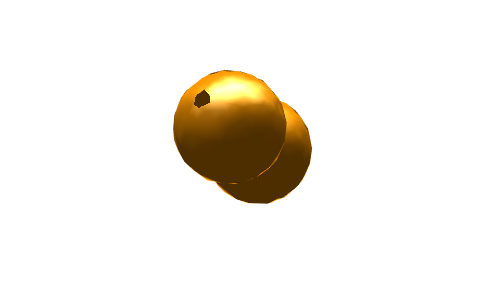

% Plot the lnps to do quality control
% Blebbed LNPs are a great simplification of the real structure, more
% accurate modelling would require different mesh approach
tau1 = blebbed_lnp{104,1}.tau_lipid_out;
tau2 = blebbed_lnp{104,1}.tau_aqueous_out;
tau3 = blebbed_lnp{104,1}.tau_interface;

figure;
plot(tau1);
plot(tau2);
plot(tau3);
axis equal; grid on; camlight;

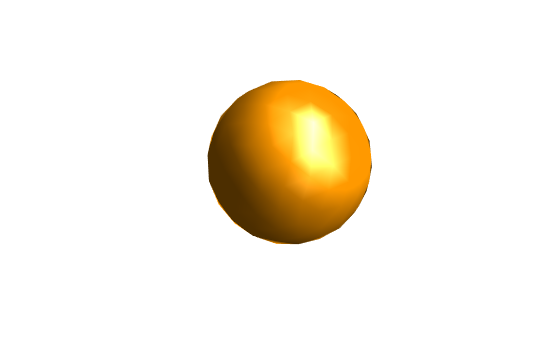

% Plot the lnps to do quality control
% Blebbed LNPs are a great simplification of the real structure, more
% accurate modelling would require different mesh approach
tau1 = empty_lnp{4,1}.tau;

figure;
plot(tau1);
axis equal; grid on; camlight;